Zadanie 1


clear all; close all;

syms t t1 t2 offset x 

T0 = 1.0;		% okres
t1 = -0.5; 
t2 = t1+T0;
offset = T0/4;

f0 = 1/T0;		% czestotliwosc
w0 = 2*pi*f0;	% pulsacja

% granice ca³kowania
BND = [t1,t2] + offset; 

x = triangularPulse(t1,0,t2,t-offset)-0.5;
idx = find(diff(sign(x)) ~= 0);
value=x(idx)

$$value = \mathrm{triangularPulse}\left(-\frac{1}{2},0,\frac{1}{2},t-\frac{1}{4}\right)-\frac{1}{2}$$

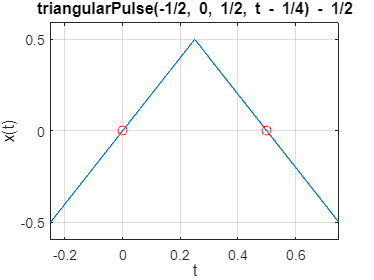

figure;

ezplot(x,BND); 
grid on; 
ylabel('x(t)');
hold on
plot([0,0.5],0,'ro')

Zadnie 2

NT = 16;
X=[];
ind = -NT : NT;
for n = ind
Xn = (1/T0)*int(x*exp(-i*w0*n*t),t,BND)
X(n + NT + 1) = Xn;
end

$$Xn = 0$$

$$Xn = -\frac{2\,\mathrm{i}}{225\,\pi^{2}}$$

$$Xn = 0$$

$$Xn = \frac{2\,\mathrm{i}}{169\,\pi^{2}}$$

$$Xn = 0$$

$$Xn = -\frac{2\,\mathrm{i}}{121\,\pi^{2}}$$

$$Xn = 0$$

$$Xn = \frac{2\,\mathrm{i}}{81\,\pi^{2}}$$

$$Xn = 0$$

$$Xn = -\frac{2\,\mathrm{i}}{49\,\pi^{2}}$$

$$Xn = 0$$

$$Xn = \frac{2\,\mathrm{i}}{25\,\pi^{2}}$$

$$Xn = 0$$

$$Xn = -\frac{2\,\mathrm{i}}{9\,\pi^{2}}$$

$$Xn = 0$$

$$Xn = \frac{2\,\mathrm{i}}{\pi^{2}}$$

$$Xn = 0$$

$$Xn = -\frac{2\,\mathrm{i}}{\pi^{2}}$$

$$Xn = 0$$

$$Xn = \frac{2\,\mathrm{i}}{9\,\pi^{2}}$$

$$Xn = 0$$

$$Xn = -\frac{2\,\mathrm{i}}{25\,\pi^{2}}$$

$$Xn = 0$$

$$Xn = \frac{2\,\mathrm{i}}{49\,\pi^{2}}$$

$$Xn = 0$$

$$Xn = -\frac{2\,\mathrm{i}}{81\,\pi^{2}}$$

$$Xn = 0$$

$$Xn = \frac{2\,\mathrm{i}}{121\,\pi^{2}}$$

$$Xn = 0$$

$$Xn = -\frac{2\,\mathrm{i}}{169\,\pi^{2}}$$

$$Xn = 0$$

$$Xn = \frac{2\,\mathrm{i}}{225\,\pi^{2}}$$

$$Xn = 0$$

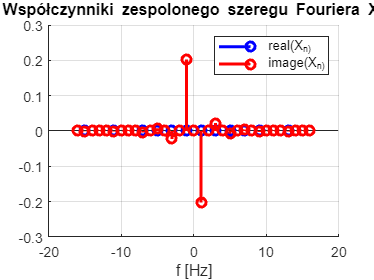

figure; hold on;
stem(ind*f0,real(X),'b','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2);
grid on
legend('real(X_n)','image(X_n)','Location','NorthEast')
title('Współczynniki zespolonego szeregu Fouriera X_n')

Zadanie 3

NT = 16;
X=[];
An=[];
Bn=[];
ind = -NT : NT;
for i = ind
An(i)=(1/T0)*int(x*cos(-w0*i*t),t,BND)
Bn(i)=(1/T0)*int(x*sin(-w0*i*t),t,BND)
X(i+NT+1) = [An,Bn]
end

Array indices must be positive integers or logical values.


stem(ind*f0,real(X),'b','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2);
grid on



step = (BND(2) - BND(1))/1000;
tt = [BND(1)-T0 : step: BND(2) + T0];
xx = zeros(1,length(tt));
xx = xx + a(1); % skladowa stala

Unrecognized function or variable 'a'.

figure
plot(tt,xx,'m'); grid on, hold on;
plot([0,0],[-0.6,0.6],'w.')
xlabel('t'); ylabel('x(t)');
pause(0.5)
for n = 1 : NT
xx_n = 2*(a(n+1)*cos(w0*n*tt) + b(n+1)*sin(w0*n*tt));
xx = xx + xx_n;
plot(tt,xx_n,'r'); plot(tt,xx,'m');
title(sprintf('n = %d',n+1)); pause(0.5)
end
plot(tt,xx,'k','LineWidth',3);
title('Rekonstrukcja sygnaªu ci¡gªego na podstawie szeregu Fouriera')